clear; clc; close all;
addpath("utils/")
dataPath = 'DataSets/BalancingTests/staticbalance.csv';
[~, timedelta, data] = parseDataSet(dataPath);

pitch = data(:,1);
xpos = data(:,21);
dt = round(mean(timedelta)) *1e-9;

duration = (length(pitch) * dt)

duration = 95.8179

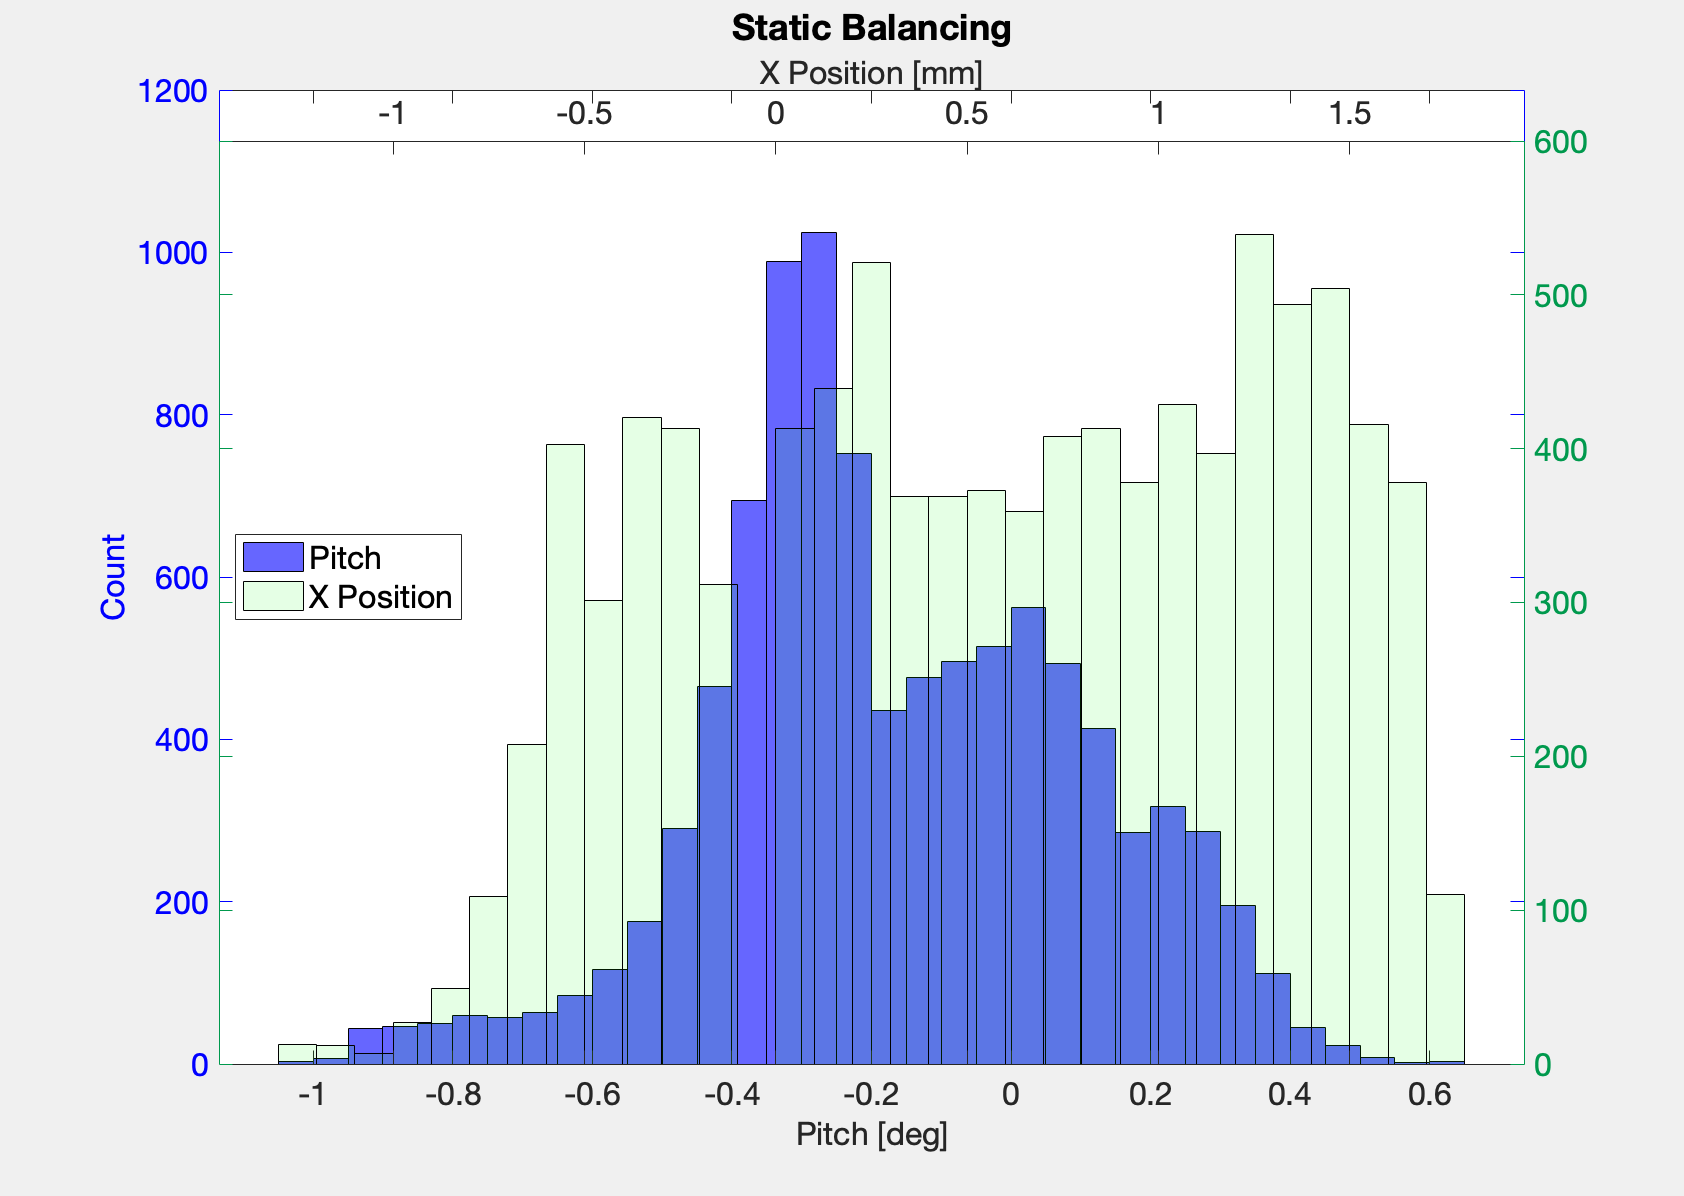


fig  = figure;
ax1 = axes;
h1 = histogram(ax1, pitch, 'FaceColor','b'); % store handle
ax1.YColor = 'b';
xlabel(ax1, 'Pitch [deg]');
ylabel(ax1, 'Count');
hold(ax1, 'on');
ax2 = axes;
% offset initial position
h2 = histogram(ax2, (xpos -xpos(1))*100,'FaceAlpha', 0.1, 'FaceColor','g'); % store handle
ax2.Color = 'none';
ax2.YColor = [0, 0.6, 0.3];
ax2.YAxisLocation = 'right';
ax2.XAxisLocation = 'top';
xlabel(ax2, 'X Position [mm]');

legend([h1, h2], {'Pitch', 'X Position'}, Location='west');
fontsize(16,'points')
plottitle = 'Static Balancing';
title(plottitle, FontSize=18);

folderpath = fullfile("..", "Docs", "Y3Report", "Images", "Graphs", filesep);
filepath = fullfile(folderpath, plottitle + ".pdf");
set(fig, 'Units', 'inches', 'Position', [0 0 11.7 8.3]);
exportgraphics(fig, filepath);
set(gcf,'Visible', 'on');